# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.9 用MARLAB生成一个模拟光斑

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

原问题：[https://www.zhihu.com/question/531978446/answer/2485702356](https://www.zhihu.com/question/531978446/answer/2485702356)

# 如何用MARLAB生成一个模拟光斑？

生成一个不规则的模拟光斑 类似于这种

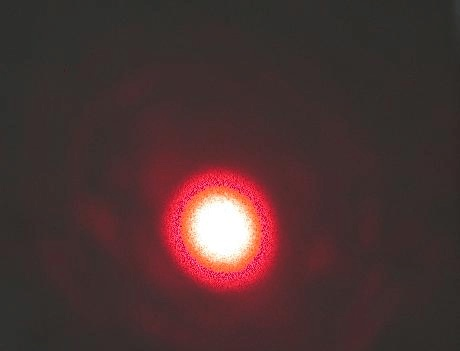

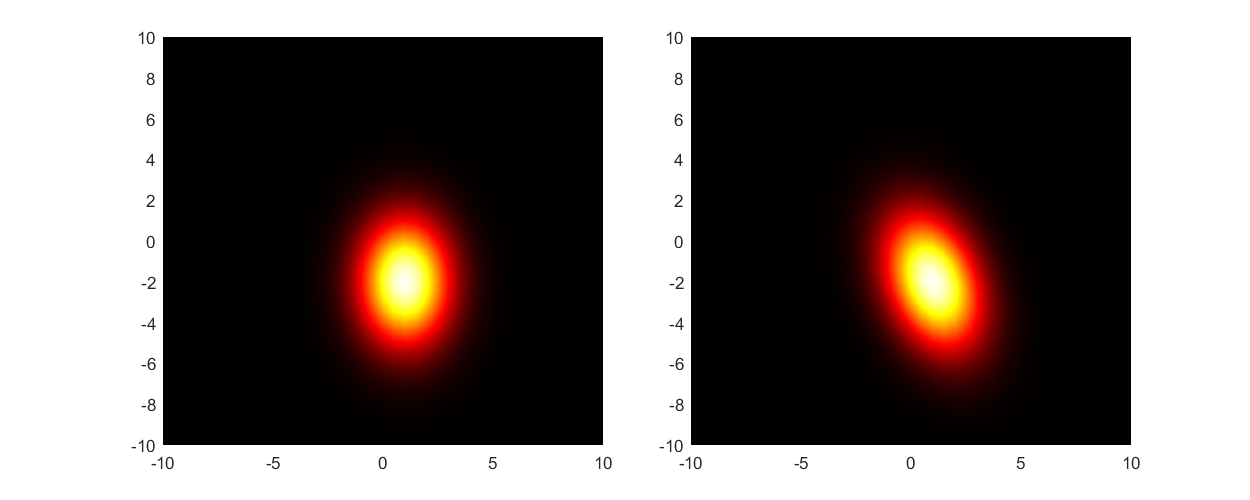

clear;clc;
[x, y] = meshgrid(-10:0.5:10);
a = 2;
b = 3;
x0 = 1;
y0 = -2;
z1 = exp(-((x - x0).^2/a^2 + (y - y0).^2/b^2));
z2 = exp(-((x - x0).^2/a^2 + (y - y0).^2/b^2 + 0.1*(x - x0).*(y - y0)));
figure('Position', [0, 0, 1000, 400]);
tiledlayout(1, 2, 'TileSpacing', 'compact');
nexttile
surf(x, y, z1);
view(0, 90);
shading interp
colormap(hot);
nexttile
surf(x, y, z2);
view(0, 90);
shading interp
colormap(hot);